% Mohamed Benalla Closed System Pendulum
% Tutorial mathworks.com/help/symbolic/simulate-physics-pendulum-swing.html

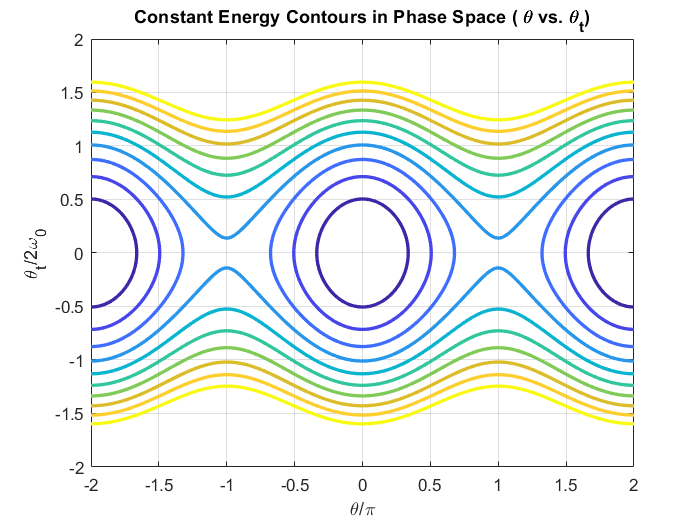

%Visualization of Energy Conservations -past a certain energy threshold, the
%pendulum swings over the top
syms theta theta_t omega_0
E(theta, theta_t, omega_0) = (1/2)*(theta_t^2+(2*omega_0*sin(theta/2))^2);
Eplot(theta, theta_t) = subs(E, omega_0,omega_0Value);

figure;
fc = fcontour(Eplot(pi*theta, 2*omega_0Value*theta_t), 2*[-1 1 -1 1], ...
    'LineWidth', 2, 'LevelList', 0:5:50, 'MeshDensity', 1+2^8);
grid on;
title('Constant Energy Contours in Phase Space ( \theta vs. \theta_t)');
xlabel('\theta/\pi');
ylabel('\theta_t/2\omega_0')

% Solve
syms theta(t) theta_t(t) omega_0
eqs = [(diff(theta) == theta_t);
        diff(theta_t) == -omega_0^2*sin(theta)]

$$eqs(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\theta \left(t\right)=\theta_{t}\left(t\right)\\ \frac{\partial }{\partial t}\theta_{t}\left(t\right)=-{\omega_{0}}^{2}\,\sin\left(\theta \left(t\right)\right) \end{array}\right)$$

eqs = subs(eqs, omega_0, omega_0Value)

$$eqs(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}\theta \left(t\right)=\theta_{t}\left(t\right)\\ \frac{\partial }{\partial t}\theta_{t}\left(t\right)=-\frac{981\,\sin\left(\theta \left(t\right)\right)}{100} \end{array}\right)$$

vars = [theta, theta_t];
[M, F] = massMatrixForm(eqs, vars)

$$M = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

$$F = \left(\begin{array}{c} \theta_{t}\left(t\right)\\ -\frac{981\,\sin\left(\theta \left(t\right)\right)}{100} \end{array}\right)$$

f = M\F

$$f = \left(\begin{array}{c} \theta_{t}\left(t\right)\\ -\frac{981\,\sin\left(\theta \left(t\right)\right)}{100} \end{array}\right)$$

f = odeFunction(f, vars)

f = function_handle with value:
    @(t,in2)[in2(2,:);sin(in2(1,:)).*(-9.81e+2./1.0e+2)]


% 2 is threshold
x0 = [0; 1.7 * omega_0Value];
tStart = 0;
tEnd = 10;
sols = ode45(f,[tStart tEnd], x0)

sols = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1×41 double]
          y: [2×41 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


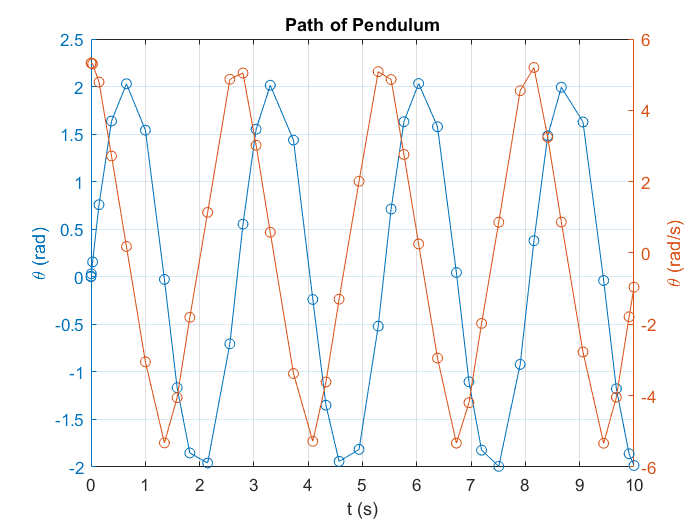

%plot
figure;
yyaxis left;
plot(sols.x, sols.y(1,:), '-o')
ylabel('\theta (rad)')

yyaxis right;
plot(sols.x, sols.y(2,:), '-o')
ylabel('\theta (rad/s)')

grid on;
title('Path of Pendulum')
xlabel('t (s)')

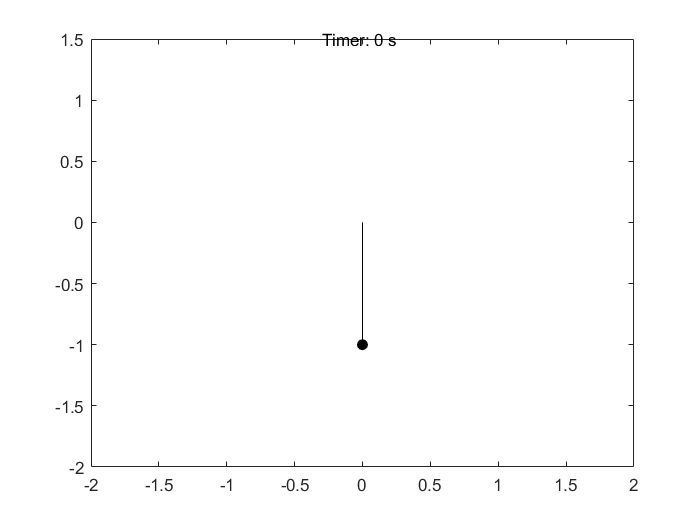

x_pos = @(t) sin(deval(sols,t,1));
y_pos = @(t) -cos(deval(sols,t,1));
figure;
fanimator(@(t) plot(x_pos(t),y_pos(t),'ko','MarkerFaceColor','k'));
hold on;
fanimator(@(t) plot([0 x_pos(t)],[0 y_pos(t)],'k-'));
fanimator(@(t) text(-0.3,1.5,"Timer: " + num2str(t,2)+ " s"));

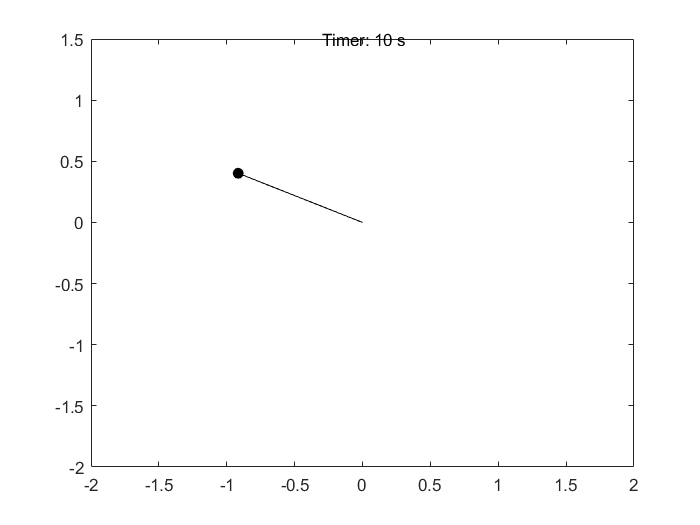

playAnimation